# Estrategia de cobertura para un dron multirrotor

La estrategia de cobertura es el proceso de búsqueda de un camino óptimo para un dron dada un área geográfica. Utilizando el objeto [`uavCoveragePlanner`](https://es.mathworks.com/help/uav/ref/uavcoverageplanner.html) se puede inspeccionar una zona dada, pasando por una serie de puntos que definen la región de interés. Se va a utilizar un Live Script de Matlab, un archivo interactivo que combina código, salida de código, gráficos y texto en un solo documento.

Se han cargado los paquetes Mapping Toolbox, Robotics System Toolbox y UAV Toolbox.

Fuente: https://es.mathworks.com/help/uav/ug/optimally-survey-and-customize-coverage-of-region-of-interest-using-coverage-planner.html

## Definir la región de interés

Para comenzar con la estrategia de cobertura, es necesario definir la región de interés como un polígono o conjunto de polígonos. En primer lugar, se crea el eje y se establecen los límites de latitud y longitud. Se calcula la media de los límites para obtener el geocentro del área vista. Además, se establece una altura de referencia sobre el nivel del mar para la visualización de la región geográfica en el mapa.

El rango de latitud y longitud elegidos pertenece al área de un bosque de secuoyas próximo a Cabezón de la Sal, en Cantabria, una reserva forestal con rutas de senderismo entre cientos de secuoyas de gran altura.

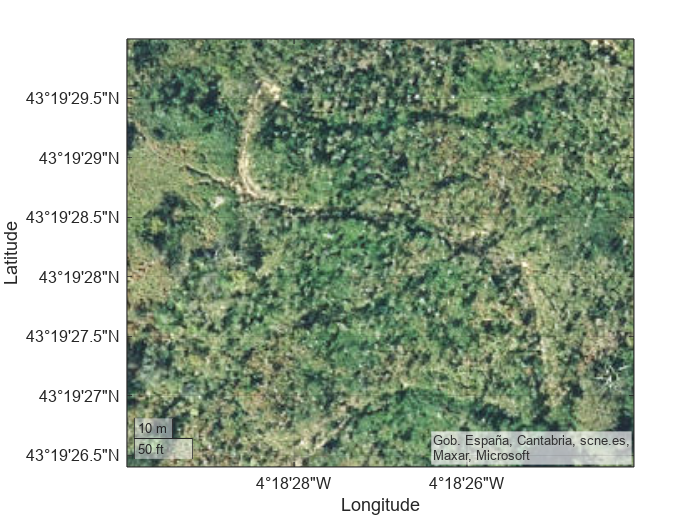

gax = geoaxes(Basemap="satellite");
latlimits = [43.324 43.325];
lonlimits = [-4.308 -4.307];
geolimits(latlimits,lonlimits);
geocenter = [mean(latlimits) mean(lonlimits) 0];
refHeight = 100;
hold on

Para definir los vértices del polígono, se llama a la función `helperPlotTakeoffROILanding` con varios argumentos. Esta función toma como entrada el objeto `geoaxes` anterior en el que se situarán los puntos de interés y la ruta de vuelo. También se proporcionan los siguientes argumentos:

- `takeoffLat` y `takeoffLon`: las coordenadas de latitud y longitud del punto de despegue.

- `landLat` y `landLon`: las coordenadas de latitud y longitud del punto de aterrizaje.

- `llapoints`: una matriz de puntos de ruta intermedia. Cada fila de la matriz representa un punto con las coordenadas de latitud, longitud y altitud respectivamente.

Si el argumento `interactiveROI` de la función se establece en* true*, permite al usuario seleccionar un área de interés (ROI) en los ejes geográficos (si el usuario conoce los puntos de interés de una región porque ha realizado un estudio previo, puede elegirlos y continuar con la planificación). Si `interactiveROI` se establece en false, la función utiliza el área de interés predefinida en una variable `predefinedROI` que toma la función. En este caso, para elegir la región que se va a estudiar y los puntos de lanzamiento y aterrizaje, he activado `interactiveROI `y los he escogido del mapa, para después introducirlos manualmente y tenerlos fijos. He escogido las áreas con menos árboles del bosque para el despegue (en azul) y aterrizaje (en naranja), y aquellos lugares más frondosos para la vigilancia.

Nota: intentar que no haya intersecciones en el polígono, ni que sea completamente convexo, porque si no da errores en pasos posteriores.

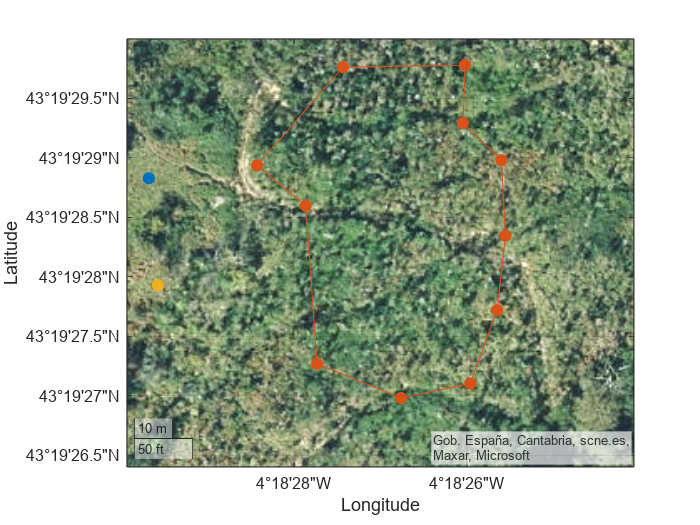

interactiveROI = false;

% Combinar coordenadas en matriz (lat, lon, alt)
llaPoints = [    43.3249341792500	-4.30762047196742, 0; 
                   43.3249390101332	-4.30722831494243, 0;
                   43.3248037452596	-4.30723496167167, 0; 
                   43.3247167891104	-4.30711199718078, 0;
                   43.3245404609813	-4.30709870372231, 0;
                   43.3243665478048	-4.30712529063926, 0;
                   43.3241950496014	-4.30721169811934, 0;
                   43.3241612329971	-4.30743436354878, 0;
                   43.3242409435343	-4.30770355608289, 0;
                   43.3246105092035	-4.30774011309369, 0;
                   43.3247047118576	-4.30789631123076, 0;
                   43.3249341792500	-4.30762047196742, 0];

% En coordenadas cartesianas:
xyzPoints = [-9.77154780297688	48.2369070514911;
            22.0365250451388	48.7736136339637;
            21.4974051664915	33.7458131734758;
            31.4711229238801	24.0850666358357;
            32.5493626814628	4.49517704024552;
            30.3928831663693	-14.8264136001286;
            23.3843247421533	-33.8797029849568;
            5.32380880296592	-37.6366959727354;
            -16.5105462876891	-28.7809301317462;
            -19.4757056210058	12.2774687559660;
            -32.1450227724233	22.7432951902114;
            -9.77154780297688	48.2369070514911];

% Coordenadas del punto de despegue y aterrizaje
takeoffLat = 43.3246746513393;
takeoffLon = -4.30824413034954;
landLat = 43.3244246515436;
landLon = -4.30821516960080;


% Obtener puntos de interés y ruta de vuelo
helperPlotTakeoffROILanding(gax, takeoffLat, takeoffLon, landLat, landLon, llaPoints);

Si `interactiveROI` es verdadera, se permitirá la selección interactiva de los puntos de despegue, aterrizaje y polígono de vuelo en el mapa. Se comienza seleccionando la posición de inicio, y se va definiendo el polígono haciendo click en la región. Dando a Enter se termina la selección, y se puede elegir la posición final:

% if(interactiveROI)
%     [visLimitsLat,visLimitsLon] = geolimits; 
%     [takeoffLat,takeoffLon] = helperTakeoffSelectionFcn(gax,visLimitsLat,visLimitsLon);
%     [llapoints,xyzpoints] = helperPolygonSelectionFcn(gax,visLimitsLat,visLimitsLon,geocenter);
%     [landLat,landLon] = helperLandSelectionFcn(gax,visLimitsLat,visLimitsLon);
% end

## Dividir la región de interés en subregiones

Para cubrir un área de forma óptima, se propone descomponer la región en áreas convexas más simples. En este caso, al escoger los puntos manualmente, ya se obtienen las coordenadas cartesianas directamente (`xyzPoints`), pero pueden calcularse a partir de unas coordenadas geodésicas dadas utilizando la función `geodetic2ecef `por ejemplo, la elipsoide WGS84.  

A continuación, se han extraído las columnas 1 y 2 de la matriz `xyzPoints` para obtener las coordenadas Este-Norte de cada punto, que se pasan como argumento a la función `coverageDecomposition`. Finalmente, se crea una celda vacía llamada `subAreasLLA` para almacenar las coordenadas geodésicas de cada subárea.

% wgs84 = wgs84Ellipsoid('kilometer');
% xyzPoints = zeros(size(llaPoints));
% for i = 1:size(llaPoints,1)
%     [x,y,z] = geodetic2ecef(wgs84, llaPoints(i,1), llaPoints(i,2), llaPoints(i,3));
%     xyzPoints(i,:) = [x y z];
% end

subAreasEN = coverageDecomposition(xyzPoints(:,1:2));
subAreasLLA = cell(1,numel(subAreasEN));

Ahora se toma las subáreas en coordenadas Este-Norte generadas previamente y las transforma en coordenadas geográficas latitud-longitud-altitud utilizando la función `enu2lla`. El primer `for` recorre cada subárea en E-N, y para cada una se define la altitud a una altura de referencia `refHeight` (definida anteriormente). Luego, se crea una matriz `localENU` con las coordenadas east-north-altitude de la subárea. Finalmente, se llama a la función `enu2lla` para transformar las coordenadas east-north-altitude en latitud-longitud-altitud, utilizando el centro geográfico `geocenter` y el argumento `"flat"` para indicar que se trata de una proyección plana. Las coordenadas latitud-longitud de cada subárea se almacenan en la variable `subAreasLLA`.

for i = 1:1:numel(subAreasEN)
    altitude = refHeight*ones(size(subAreasEN{i},1),1);
    localENU = [subAreasEN{i}(:,1) subAreasEN{i}(:,2) altitude];
    subArea = enu2lla(localENU,geocenter,"flat");
    subAreasLLA{i} = subArea(:,1:2);
end

## Crear una estrategia de cobertura y una planificación para una región

Para planificar la ruta de cobertura, es necesario crear un espacio de cobertura utilizando los polígonos que representan la región de interés. Una vez que se tiene el espacio de cobertura, se puede crear un planificador. El objetivo es cubrir óptimamente cada subregión minimizando el número de giros y  la distancia de conexión entre subregiones. La distancia de conexión es la distancia que el UAV debe recorrer para llegar al siguiente polígono a cubrir. 

La función `uavCoverageSpace `utiliza los siguientes argumentos:

- `Polygons`: una lista de polígonos que representan las áreas que se desean cubrir. Estos polígonos se definen en términos de la latitud, longitud y altura (`subAreasLLA`).

- `UnitWidth`: el ancho de la unidad de muestreo, que se utiliza para especificar el espaciado entre barridos paralelos adyacentes.

- `Sidelap`: el porcentaje de superposición entre las celdas adyacentes.

- `ReferenceHeight`: la altura de referencia a la que se encuentra el dron.

- `UseLocalCoordinates`: indica si se deben utilizar coordenadas locales en lugar de coordenadas geográficas para la planificación de la ruta del dron.

- `ReferenceLocation`: la ubicación de referencia a partir de la cual se definen las coordenadas locales.

cs = uavCoverageSpace(Polygons=subAreasLLA, ...
                      UnitWidth=10, ...
                      Sidelap=0.4, ...
                      ReferenceHeight=refHeight, ...
                      UseLocalCoordinates=false, ...
                      ReferenceLocation=geocenter);

Se muestra el espacio de cobertura en la imagen:

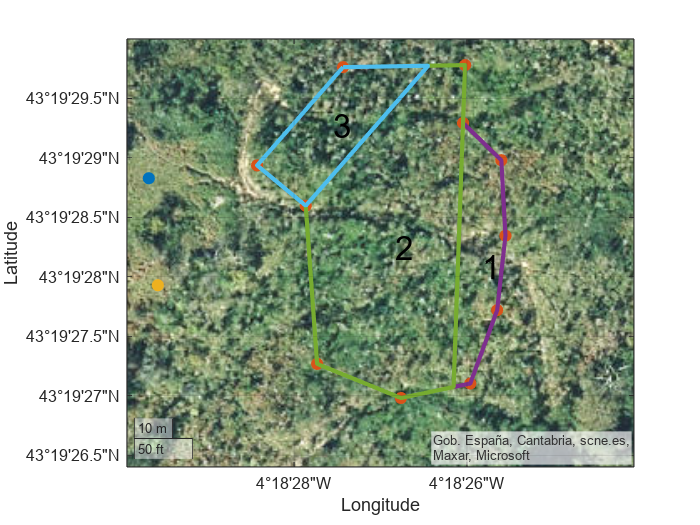

ax = cs.show(Parent=gax,LineWidth=2.5);

Se crea el planificador y la estrategia de cobertura comenzando por la ubicación de salida hasta la de aterrizaje.

cp = uavCoveragePlanner(cs);
[wpts,solnInfo] = plan(cp,[takeoffLat takeoffLon 0],[landLat landLon 0]); 

Se muestra dicha estrategia:

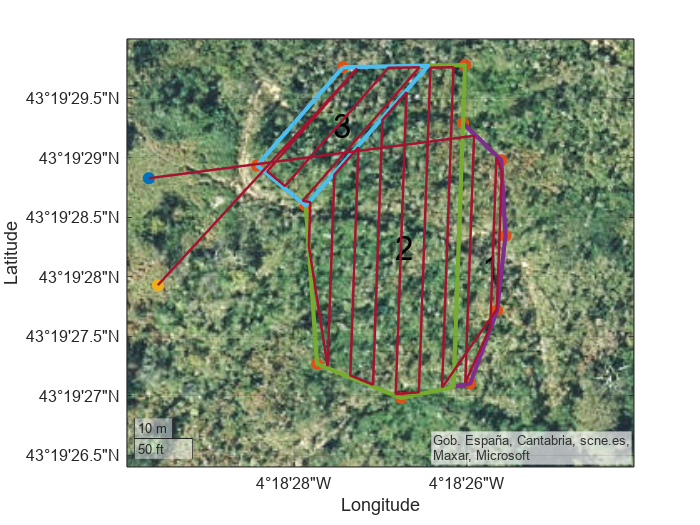

path1 = geoplot(gax,wpts(:,1),wpts(:,2),LineWidth=1.5);
hold off

Se calcula el coste de transición en metros, incluyendo la distancia desde la localización de despegue hasta el primer polígono y del último polígono al lugar de aterrizaje:

connectionDistancePath1 = solnInfo.TransitionCost

connectionDistancePath1 = 284.3769

## Recorrido personalizado

Aunque el planificador determina de forma automática el patrón de barrido en cada subregión, se puede personalizar para mejorar la actuación de la nave. Por ejemplo, es posible que desee estudiar cultivos o vegetación en una cierta orientación.

Se puede, por ejemplo, modificar el ángulo de barrido del segundo y tercer polígono en a 90º:

cs.setCoveragePattern(2,SweepAngle=90);
cs.setCoveragePattern(3,SweepAngle=90);

Otra modificación que puede hacerse es elegir el mejor candidato para comenzar la misión. Por ejemplo, la zona 3 es la más cercana al lanzamiento del dron y puede ser de interés que barra primero esta región, por lo que establecemos que el planificador comience en el tercer polígono:

cp.SolverParameters.StartingArea = 3;

Se actualiza el planificador:

[wpts,custSoln] = plan(cp,[takeoffLat takeoffLon 0],[landLat landLon 0]);

Se elimina el recorrido anterior y se dibuja el nuevo:

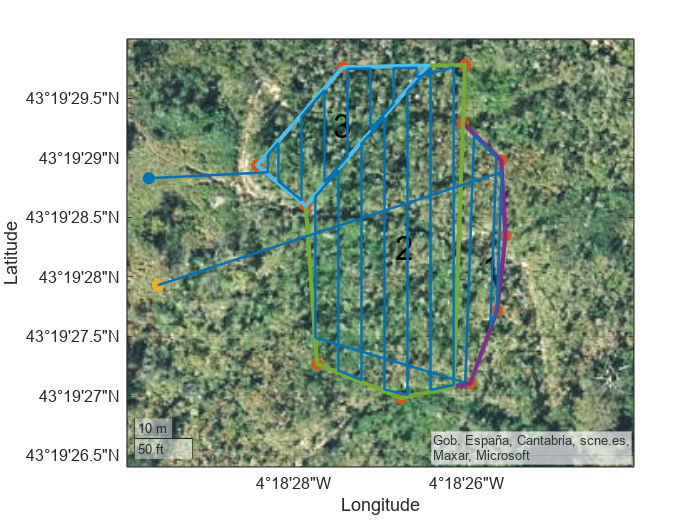

delete(path1);
hold on
path2 = geoplot(gax,wpts(:,1),wpts(:,2),LineWidth=1.5);
hold off

Se evalúa de nuevo el coste de la misión:

connectionDistancePath2 = custSoln.TransitionCost

connectionDistancePath2 = 292.8496

Parece que no ha sido de mucha utilidad este cambio, ya que el coste aumenta con respecto al anterior.

## Exportar recorrido 

Se pueden exportar los puntos de ruta a un archivo y crear una misión de UAV a partir de él. Es posible indicar la velocidad y el ángulo de giro inicial.

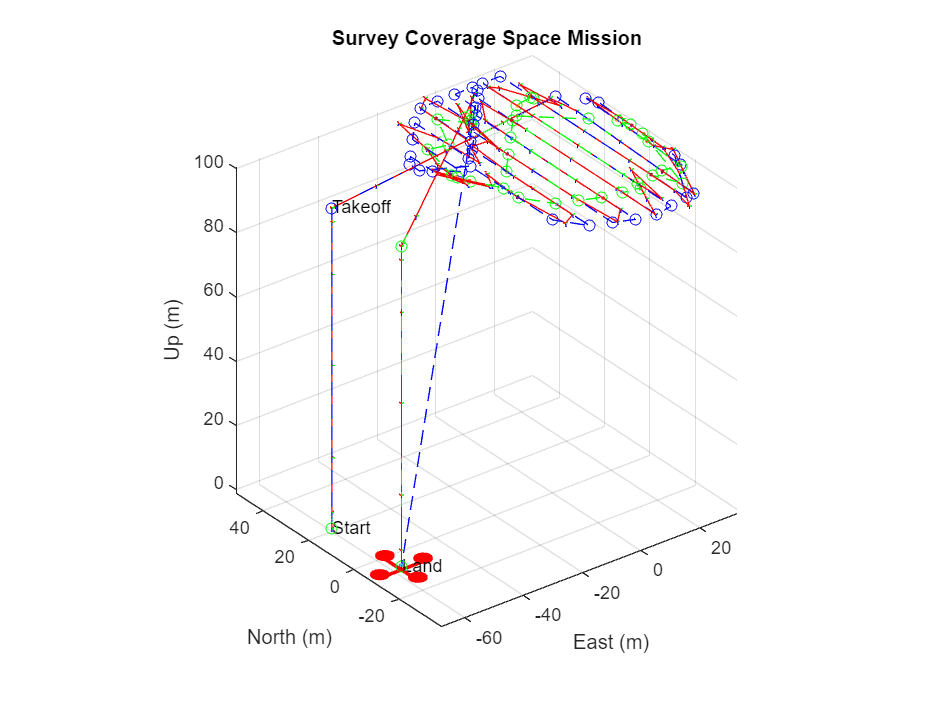

Tiempo total de vuelo: 4.1583 minutos


exportWaypointsPlan(cp,solnInfo,"customCoverage.waypoints");
mission = uavMission(PlanFile="customCoverage.waypoints",Speed=10,InitialYaw=90);
helperSimulateUAVMission(mission,geocenter)